# LSTM for UCI HAR Dataset

## DATA PREPARATION

dataFolder = "UCI HAR Dataset";

trainFolder = fullfile(dataFolder,"train","Inertial Signals");
testFolder  = fullfile(dataFolder,"test","Inertial Signals");

TRAIN DATA

% Load 9 channels
bx = readmatrix(fullfile(trainFolder,"body_acc_x_train.txt"));
by = readmatrix(fullfile(trainFolder,"body_acc_y_train.txt"));
bz = readmatrix(fullfile(trainFolder,"body_acc_z_train.txt"));

gx = readmatrix(fullfile(trainFolder,"body_gyro_x_train.txt"));
gy = readmatrix(fullfile(trainFolder,"body_gyro_y_train.txt"));
gz = readmatrix(fullfile(trainFolder,"body_gyro_z_train.txt"));

tx = readmatrix(fullfile(trainFolder,"total_acc_x_train.txt"));
ty = readmatrix(fullfile(trainFolder,"total_acc_y_train.txt"));
tz = readmatrix(fullfile(trainFolder,"total_acc_z_train.txt"));


idxes =     79
   151
   126
    28
     1
    52


numTrain = size(bx,1);

XTrain = cell(numTrain,1);

for i = 1:numTrain

    XTrain{i} = [
        bx(i,:);
        by(i,:);
        bz(i,:);
        gx(i,:);
        gy(i,:);
        gz(i,:);
        tx(i,:);
        ty(i,:);
        tz(i,:);
    ];   % 9 × 128
end

TEST DATA

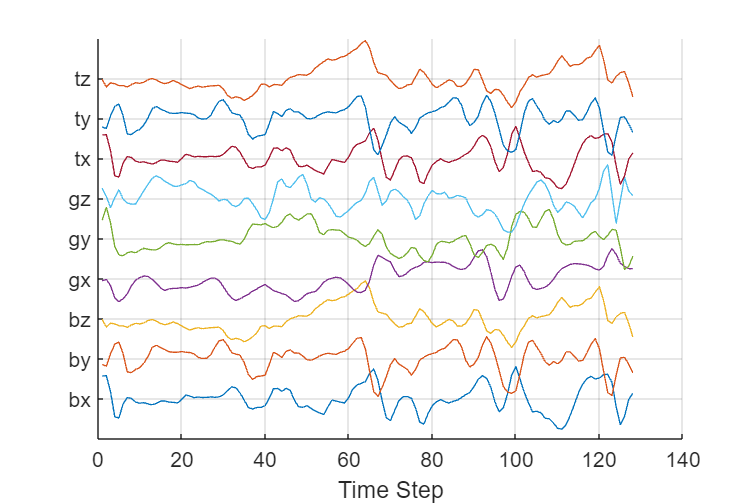

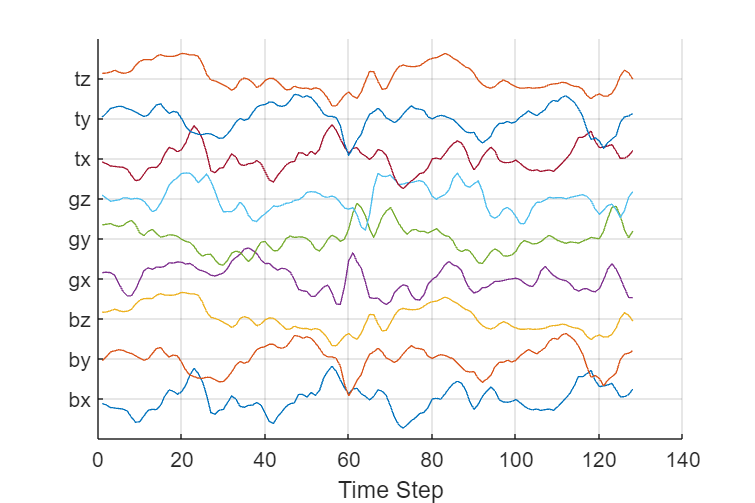

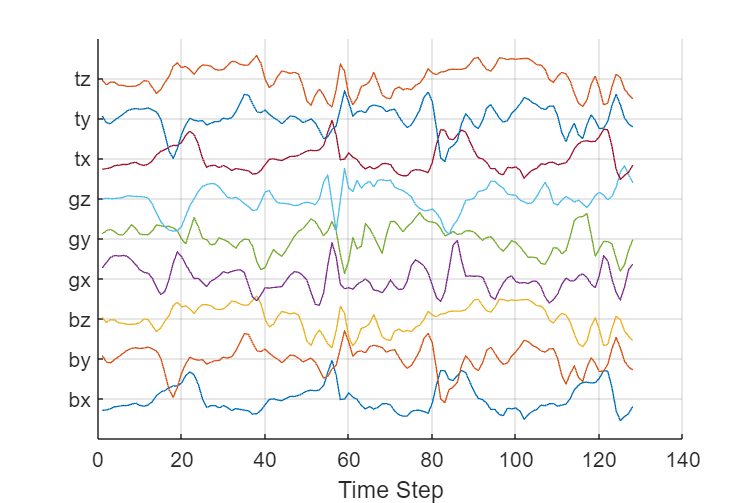

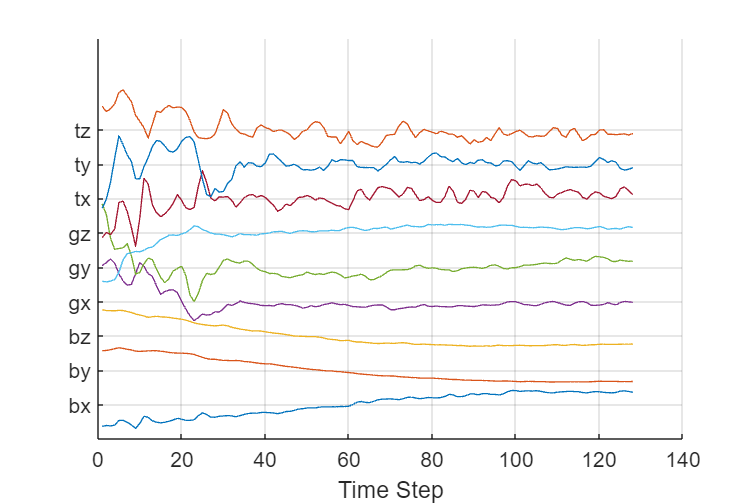

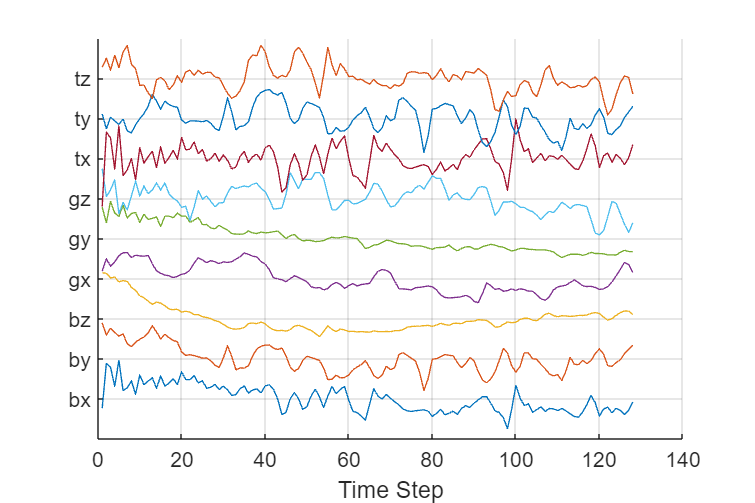

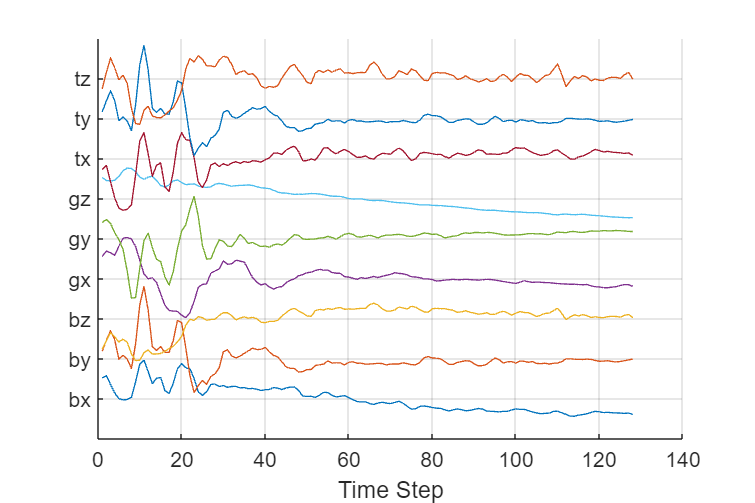

bx = readmatrix(fullfile(testFolder,"body_acc_x_test.txt"));
by = readmatrix(fullfile(testFolder,"body_acc_y_test.txt"));
bz = readmatrix(fullfile(testFolder,"body_acc_z_test.txt"));

gx = readmatrix(fullfile(testFolder,"body_gyro_x_test.txt"));
gy = readmatrix(fullfile(testFolder,"body_gyro_y_test.txt"));
gz = readmatrix(fullfile(testFolder,"body_gyro_z_test.txt"));

tx = readmatrix(fullfile(testFolder,"total_acc_x_test.txt"));
ty = readmatrix(fullfile(testFolder,"total_acc_y_test.txt"));
tz = readmatrix(fullfile(testFolder,"total_acc_z_test.txt"));

numTest = size(bx,1);


XTest = cell(numTest,1);

for i = 1:numTest

    XTest{i} = [
        bx(i,:);
        by(i,:);
        bz(i,:);
        gx(i,:);
        gy(i,:);
        gz(i,:);
        tx(i,:);
        ty(i,:);
        tz(i,:);
    ];
end

Convert labels

YTrain = categorical(readmatrix(fullfile(dataFolder,"train","y_train.txt")));
YTest  = categorical(readmatrix(fullfile(dataFolder,"test","y_test.txt")));

Verifying shape

size(XTrain{1})

numClasses = numel(categories(YTrain));
classes = categories(YTrain);


activity_labels = ["walking","walking upstairs","walking downstairs", ...
                   "sitting","standing","laying"];
% Sort counts in descending order
[countsSorted, idx] = sort(countsTrain, 'descend');

% Reorder labels accordingly
labelsSorted = activity_labels(idx);

figure('Position', [80, 80, 900, 600]);
barh(countsSorted);

yticks(1:numClasses);
yticklabels(labelsSorted);
set(gca, 'YDir', 'reverse');   % highest value on top

xlabel("Number of samples");
grid on;

exportgraphics(gcf, 'training_class_distribution_sorted.png', 'Resolution', 300);

Select 6 different labels

uniqueLabels = categories(YTrain);
numClasses = numel(uniqueLabels);

idxes = zeros(numClasses,1);

% Find one sample per class
for i = 1:numClasses
    idxes(i) = find(YTrain == uniqueLabels{i}, 1);
end

## PLOTS

idxes

for k = 1:numel(idxes)

    idx = idxes(k);
    signal = XTrain{idx};

    % Map numeric label → correct name
    labelID = double(YTrain(idx));
    label = activity_labels(labelID);

    figure('Position', [100, 100, 900, 600]);
    hold on;
    
    for i = 1:9
        s = signal(i,:);
        s = (s - mean(s)) / std(s);
        plot(s + i*3, 'LineWidth', 1);
    end
    
    yticks(3*(1:9));
    yticklabels(["bx","by","bz","gx","gy","gz","tx","ty","tz"]);
    
    
    xlabel("Time Step", 'FontSize', 18);
    set(gca, 'FontSize', 16);   % applies to both xticks and yticks

    grid on;

    filename = "training_sample_" + label + ".png";
    exportgraphics(gcf, filename, 'Resolution', 300);
end